# **Authors**

**Technical Vision**

 1. Нгуен Кхань Нгок - 345148

2. Дау Минь Шы - 343395

The task and guidelines were prepared by Andrei Zhdanov and Sergei Shavetov, ITMO University, 2025.

# **Practical Assignment No 5. Hough Transform**

Study of the Hough transformation to find of geometric primitives.

**Note.** Please note that when doing the practical assignment you are not allowed to use the “*Lenna*” image or any other image that was used either in this book or during the presentation

## Introduction

The main principle of the Hough transform is to find common *locus of points*. For example, this approach is used when designing a triangle along three given sides. At first one side of the triangle is first laid off, after that the ends of the segment are considered as the centers of circles with radii equal to the lengths of the second and third segments. The intersection of the two circles is the common locus of points, from where the segments are drawn to the ends of the first segment. In other words, a *voting* of two points was held in favor of the probable location of the third vertex of the triangle. As a result of "voting" "winning" was the point that got two "votes" (the points on the circles got one vote each, and outside them — zero). 

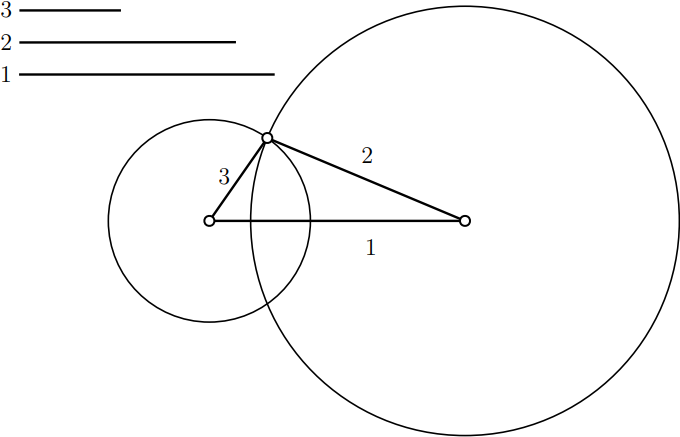

Figure 2.1 Design of a triangle by given three sides

Let’s generalize this idea for working with real data, when the image has a large number of special feature points participating in the vote. Let assume that it is necessary to search a circle of known radius 𝑅 in a binary point set, and in this set there may also be false points that do not lie on the desired circle. The set of possible circles centers for the desired radius around each characteristic point forms a circle of radius 𝑅, see Fig 2.2. Thus, the point corresponding to the maximum intersection of the number of circles will be the center of the required radius circle. 

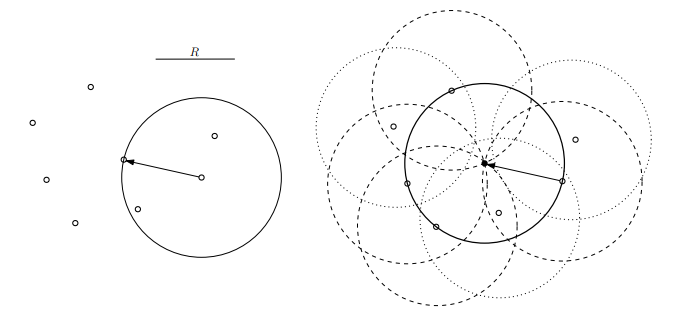

 Figure 2.2 Search a circle of known radius in a point set

The classical Hough transform, based on the considered point voting idea, was originally designed to select lines on binary images. The Hough transform uses the parameter space to search for geometric primitives. The most common parametric equation of lines is: 


$$y=kx+b,$$



$$x\cos{\Theta}+y\sin{\Theta}=\rho,$$


where $\rho$ — radius vector drawn from the origin to the line; $\Theta$ — inclination angle of the radius vector. Let the straight line in the Cartesian coordinate system be given by the first equation, from which it is easy to calculate the radius vector 𝜌 and angle Θ (secon equation). Then in the Hough parameter space the line will be represented by a point with coordinates ($\rho_0$,$\Theta_0$), see Fig. 2.3.

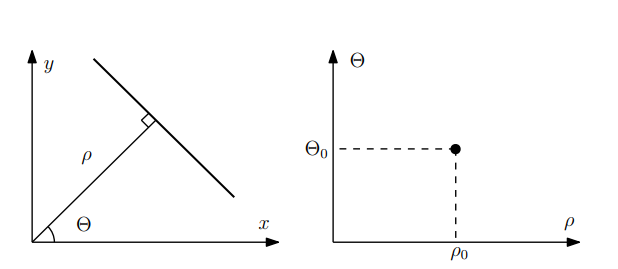

Figure 2.3 Representation of a straight line in Hough space

The Hough transform approach is for each point in the parameter space the number of votes given for it is summed up. Therefore, in discrete form, the Hough space is called *accumulator* and is a matrix 𝐴(𝜌,$\Theta$) that stores voting information. Through each point in the Cartesian coordinate system, an infinite number of straight lines can be drawn, the totality of which will generate a sinusoidal response function in the parameter space. Thus, any two sinusoidal response functions in the parameter space will intersect at the point (𝜌,$\Theta$) only if the points generating them in the initial space lie on a straight line, see fig. 2.4. Based on this, we can conclude that in order to find straight lines in the original space, it is necessary to find all the local maxima of the accumulator. 

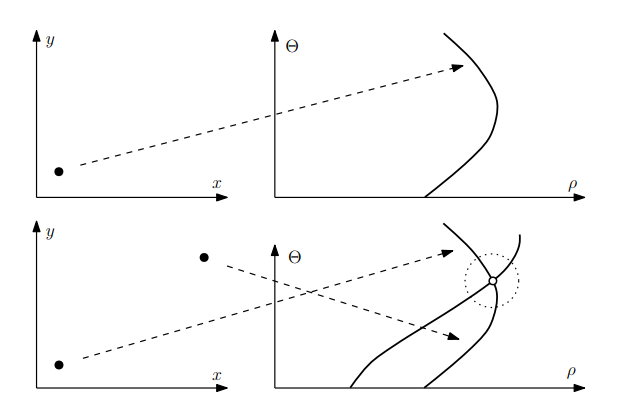

Figure 2.4. Voting procedure

The considered line search algorithm can be used in the same way to search for any other curve described in space by some function with a certain number of parameters 𝐹 = ($a_1 ,a_2 ,\ldotp \ldotp \ldotp ,a_n ,x,y$), which will only affect the dimension of the parameter space. Let us use the Hough transform to search for circles of a given radius 𝑅. It is known that a circle on a plane is described by the formula $(x-x_0)^2+(y-y_0)^2=R^2$ . The set of centers of all possible circles of radius 𝑅 passing through a feature point forms a circle of radius 𝑅 around that point. Due to this the response function in the Hough transform for finding circles is a circle of the same size centered at the voting point. Then, similarly to the previous case, it is necessary to find the local maxima of the accumulator function 𝐴(𝑥,𝑦) in the space of parameters (𝑥,𝑦), which will be the centers of the required circles.

The Hough transform is invariant to shift, scaling, and rotation. Taking into account that under projective transformations of three-dimensional space, straight lines always go only to straight lines (in the degenerate case, to points), the Hough transform makes it possible to detect lines invariantly not only to affine transformations of the plane, but also to the group of projective transformations in space.

## **Task 1. Search for Lines**

*Take three arbitrary images containing lines. Search for straight lines using various implementations of the Hough transform. Plot the found lines on the original image. Mark the start and end points of the lines. Determine the lengths of the shortest and longest lines, and calculate the number of lines found.*

### **1.1 Classic Hough Transform for Lines**

To execute the Hough line transform in MATLAB, first preprocess the image to detect edges using the Canny edge detector.

In order to detect boundaries (edges) in the image, we will use the `edge()` function. It applies various methods of edge detection based on pixel intensity gradients, which allows you to find areas of sharp changes in brightness or colour.

The syntax `I_edge = edge(I, method, threshold, direction)`:

- `I` — the input image (usually in grayscale). 

- `method` — boundary detection method. Possible values:

- ` sobel` — Sobel method (default).

- ` prewitt` — Prewitt's method.

- ` roberts` — Roberts method.

- ` log` —  Laplace Gaussian method (LoG)

- ` zerocross` — zero-crossing detection method.

- ` canny` — Canny's method (more complex and accurate).

The Canny method computes the gradient of input image using the derivative of the Gaussian filter. It then finds edges by looking for the local maxima of the gradient. This method uses two thresholds to detect the strong and weak edges. The weak edges are part of the output only if they are connected to strong edges. The block outputs a binary image of the edge detections for this method.

- `threshold` — threshold value for boundary detection. Pixels with gradient below this value are not considered as boundaries.

- `direction` — irection for methods that support this property (e.g. `sobel`, `prewitt`):

- ` horizontal` — only horizontal boundaries.

- ` vertical` — only vertical boundaries.

- ` both` — both directions (default).

`I_edge` — output binary image where the pixels belonging to the boundaries have a value of 1 (white) and the rest have a value of 0 (black).

Next, compute the Hough transform and identify peaks and lines in the image by the functions `houghpeaks()` and `houghlines()`, respectively.

Let's take a closer look at the function parameters.

`peaks = houghpeaks(H, 'Threshold')` locates peaks in the Hough transform matrix, **H**, generated by the [`hough`](https://www.mathworks.com/help/releases/R2024a/images/ref/hough.html) function. 

**numpeaks** specifies the maximum number of peaks to identify. The function returns `peaks` a matrix that holds the row and column coordinates of the peaks.

`lines = houghlines(I_edge, theta, rho, peaks)` extracts line segments in the image **I_edge** associated with particular bins in a **Hough transform**. 

`theta` and `rho` are vectors returned by function `hough()`. 

`peaks` is a matrix returned by the `houghpeaks()` function that contains the row and column coordinates of the **Hough transform** bins to use in searching for line segments. The return value `lines` contains information about the extracted line segments:

- `point1` — coordinates of the starting point of the line [x1, y1].

- `point2` — coordinates of the end point of the line [x2, y2].

- `theta `— line slope angle (in degrees).

- `rho `— distance from the coordinate origin to the line (in pixels).

Finally, plot the detected lines on the original image:

# ***Self-work***

Take **three** arbitrary images and execute the classic Hough transform. Display the found lines and print their number. 

***Notes. ****You may have to change the Hough transform parameters to match your images.*

% TODO Place your solution here
clc; close all; clear;

imageFiles = {'barcode.jpg', 'caro.jpg', 'help.jpg'};

In order to detect boundaries (edges) in the image, we will use the edge() function. It applies various methods of edge detection based on pixel intensity gradients, 

which allows you to find areas of sharp changes in brightness or colour.

The syntax I_edge = edge(I, method, threshold, direction):

          I — the input image (usually in grayscale). 

          method — boundary detection method. Possible values:

          1. sobel — Sobel method (default).

          2. prewitt — Prewitt's method.

          3. roberts — Roberts method.

          4. log —  Laplace Gaussian method (LoG)

          5. zerocross — zero-crossing detection method.

          6. canny — Canny's method (more complex and accurate).

The Canny method computes the gradient of input image using the derivative of the Gaussian filter. It then finds edges by looking for the local maxima of the gradient. 

This method uses two thresholds to detect the strong and weak edges. The weak edges are part of the output only if they are connected to strong edges. 

The block outputs a binary image of the edge detections for this method.  

          threshold — threshold value for boundary detection. Pixels with gradient below this value are not considered as boundaries.

          direction — irection for methods that support this property (e.g. sobel, prewitt):

          1. horizontal — only horizontal boundaries.

          2. vertical — only vertical boundaries.

          3. both — both directions (default).

 I_edge — output binary image where the pixels belonging to the boundaries have a value of 1 (white) and the rest have a value of 0 (black).

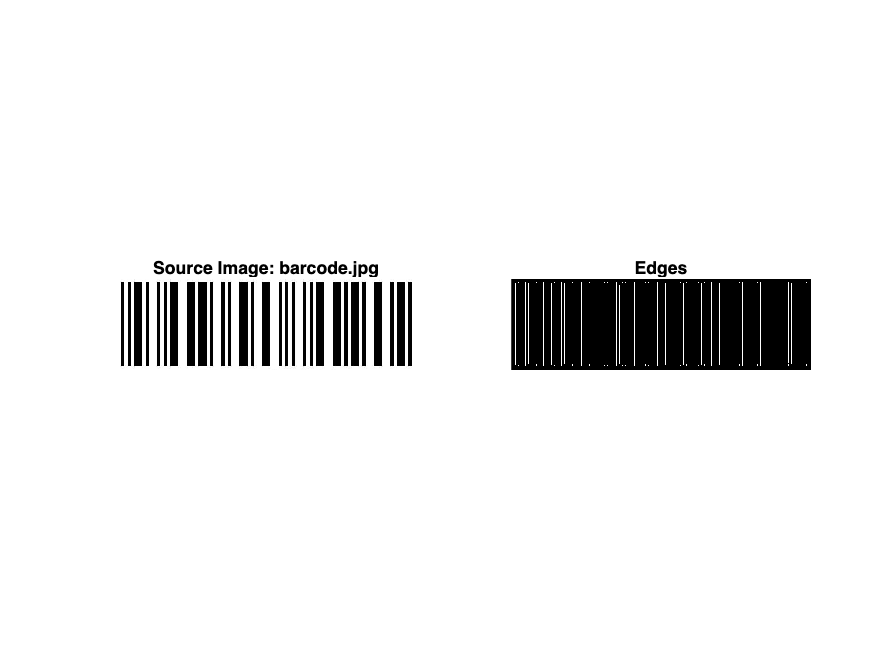

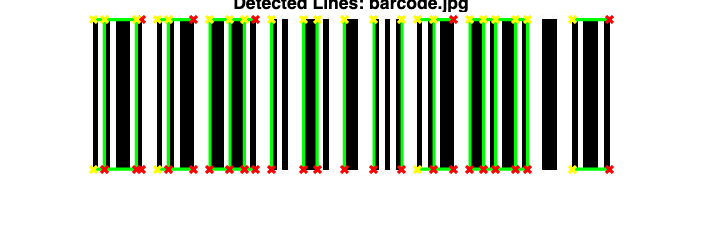

Image: barcode.jpg -> Found 30 lines.


The shortest line length is 46.00 pixels.


The longest line length is 187.00 pixels.


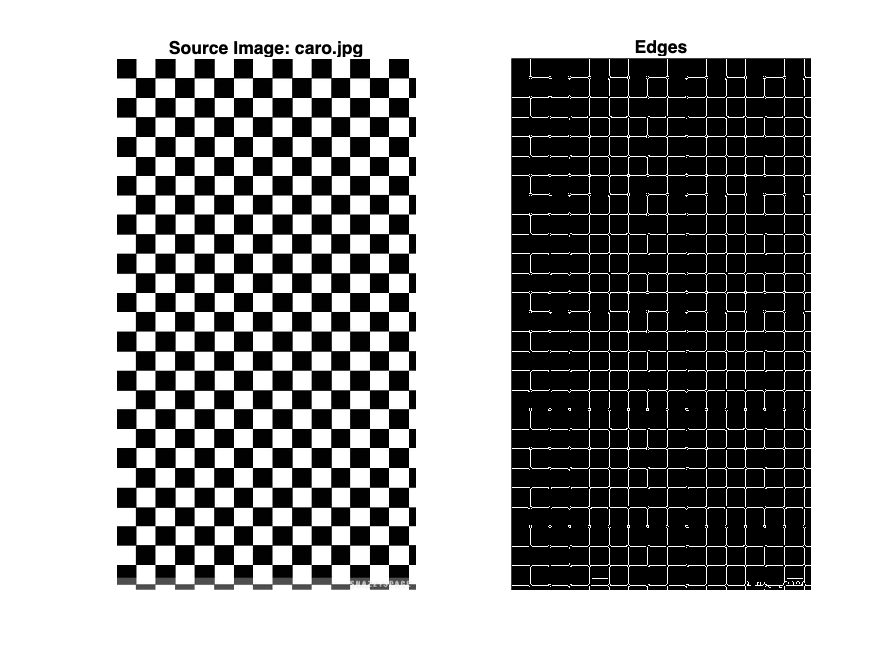

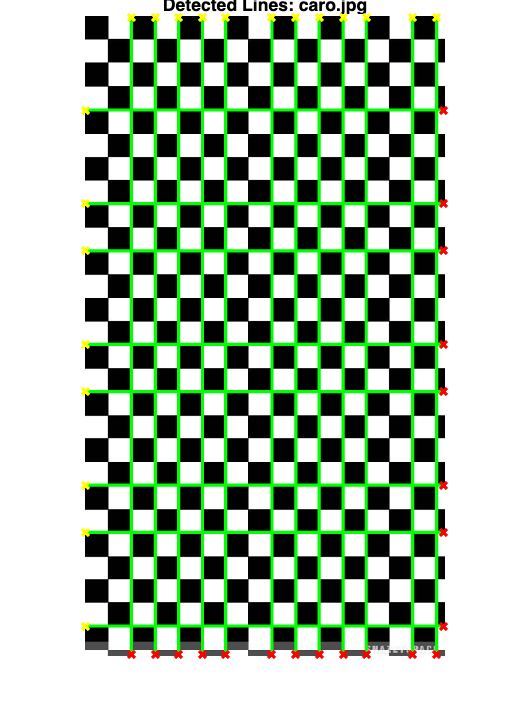

Image: caro.jpg -> Found 20 lines.


The shortest line length is 448.00 pixels.


The longest line length is 797.00 pixels.


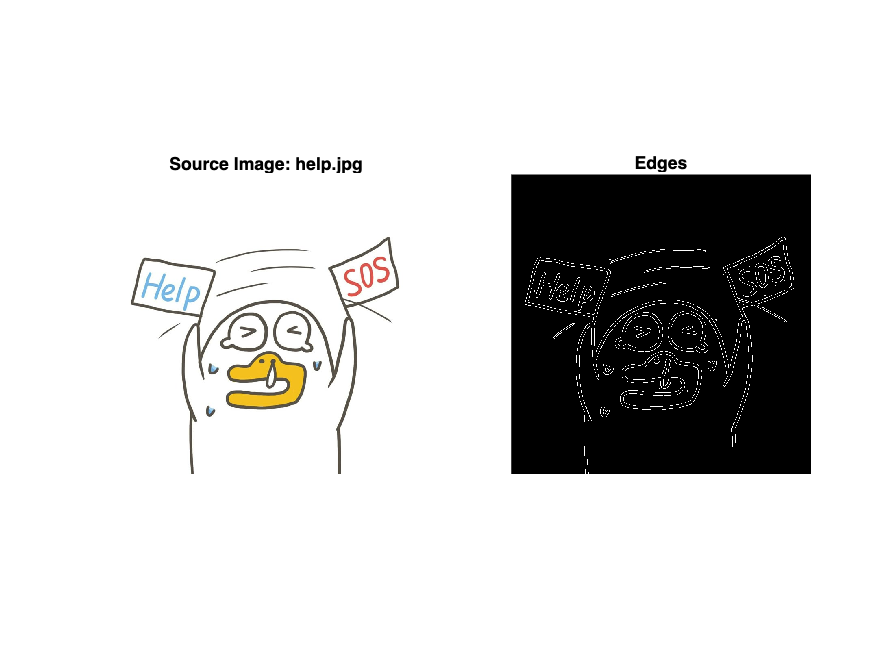

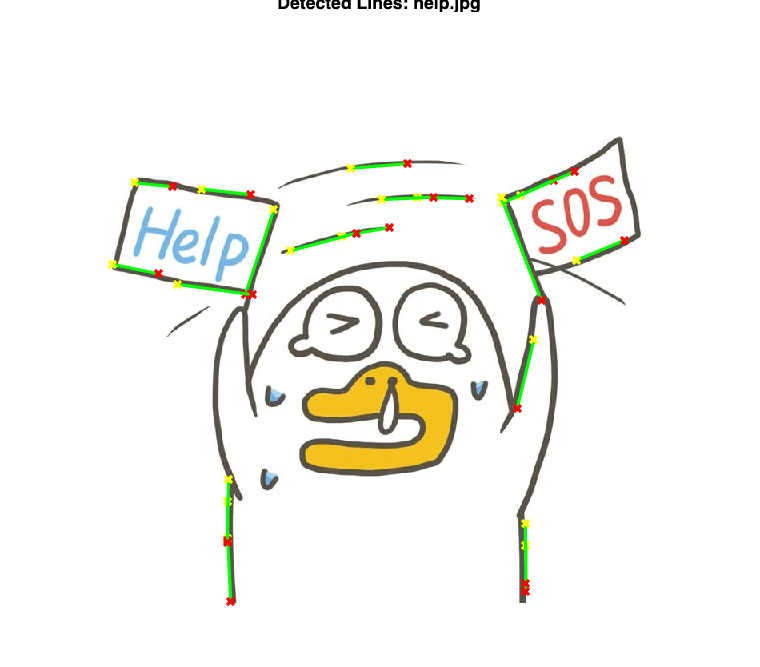

Image: help.jpg -> Found 20 lines.


The shortest line length is 45.19 pixels.


The longest line length is 138.35 pixels.


for i = 1:length(imageFiles)

    % Read an image
    I = imread(imageFiles{i});
    if isempty(I)
        error('Error reading the image.');
    end

    % Convert to grayscale if necessary
    if size(I, 3) == 3
        I_gray = rgb2gray(I);
    else
        I_gray = I;
    end

    % --- SPEED-UP: resize big images (biggest reason slow) ---
    if max(size(I_gray)) > 800
        s = 800 / max(size(I_gray));
        I_gray = imresize(I_gray, s);
        I = imresize(I, s);
    end

    % Detect edges using the Canny edge detector
    I_edge = edge(I_gray, 'canny');

    % Display the original and edge-detected images
    figure('Name',['Edges: ', imageFiles{i}], 'NumberTitle','off');
    subplot(1, 2, 1); imshow(I); 
    title(['Source Image: ', imageFiles{i}], 'Interpreter','none');  % FIX title
    subplot(1, 2, 2); imshow(I_edge); title('Edges');
    drawnow limitrate

    % Next, compute the Hough transform and identify peaks and lines in the image by the functions houghpeaks() and houghlines(), respectively.
    % Let's take a closer look at the function parameters.
    % peaks = houghpeaks(H, 'Threshold') locates peaks in the Hough transform matrix, H, generated by the hough function. 
    % numpeaks specifies the maximum number of peaks to identify. The function returns peaks a matrix that holds the row and column coordinates of the peaks.
    % lines = houghlines(I_edge, theta, rho, peaks) extracts line segments in the image I_edge associated with particular bins in a Hough transform. 
    % theta and rho are vectors returned by function hough(). 
    % peaks is a matrix returned by the houghpeaks() function that contains the row and column coordinates of the Hough transform bins to use in searching for line segments. 
    % The return value lines contains information about the extracted line segments:
    %           point1 — coordinates of the starting point of the line [x1, y1].
    %           point2 — coordinates of the end point of the line [x2, y2].
    %           theta — line slope angle (in degrees).
    %           rho — distance from the coordinate origin to the line (in pixels).

    % Compute the Hough transform
    [H, theta, rho] = hough(I_edge);

    % Find peaks in the Hough transform accumulator
    % Note: you may need to tune these parameters for your images
    thr = ceil(0.3 * max(H(:)));                 % faster/more stable than fixed 25
    peaks = houghpeaks(H, 20, 'Threshold', thr);

    % Extract lines using the Hough lines function
    % (Limit segments to speed up and reduce clutter)
    lines = houghlines(I_edge, theta, rho, peaks, 'FillGap', 10, 'MinLength', 40);

    % Finally, plot the detected lines on the original image:
    figure('Name',['Lines: ', imageFiles{i}], 'NumberTitle','off');
    imshow(I); hold on;
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'green');

        % Mark the start and end points
        plot(xy(1, 1), xy(1, 2), 'x', 'LineWidth', 2, 'Color', 'yellow');
        plot(xy(2, 1), xy(2, 2), 'x', 'LineWidth', 2, 'Color', 'red');
    end
    title(['Detected Lines: ', imageFiles{i}], 'Interpreter','none');
    hold off;
    drawnow limitrate

    % Let's calculate and display statistical information:
    num_lines = length(lines);
    fprintf('Image: %s -> Found %d lines.\n', imageFiles{i}, num_lines);

    if num_lines > 0
        line_lengths = arrayfun(@(x) norm(double(x.point1) - double(x.point2)), lines);
        shortest_length = min(line_lengths);
        longest_length = max(line_lengths);

        % Display the results
        fprintf('The shortest line length is %.2f pixels.\n', shortest_length);
        fprintf('The longest line length is %.2f pixels.\n', longest_length);
    end

end

### **1.2** **Probabilistic Hough Transform for Lines**

Let's repeat again the same steps and calculate Probabilistic Hough Transform for Lines. 

The steps related to image preframing and boundary (edge) selection remain the same.

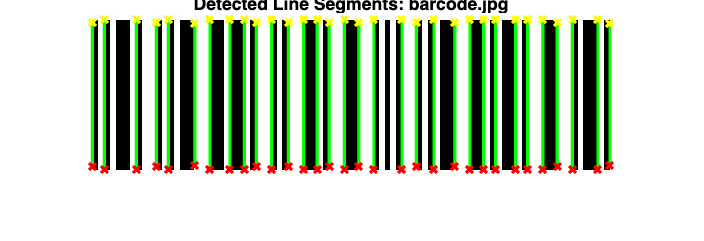

Image: barcode.jpg -> Found 32 line segments.


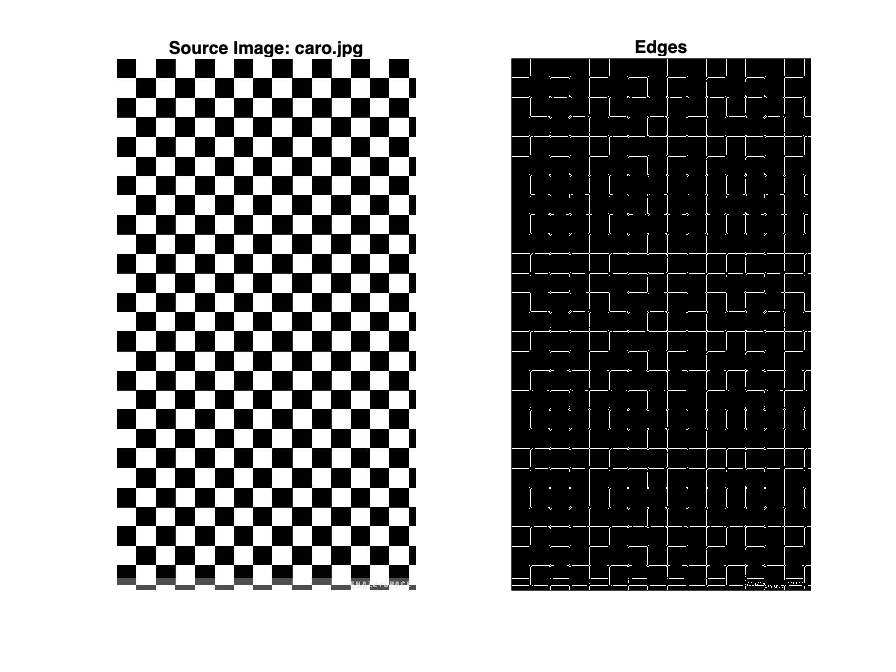

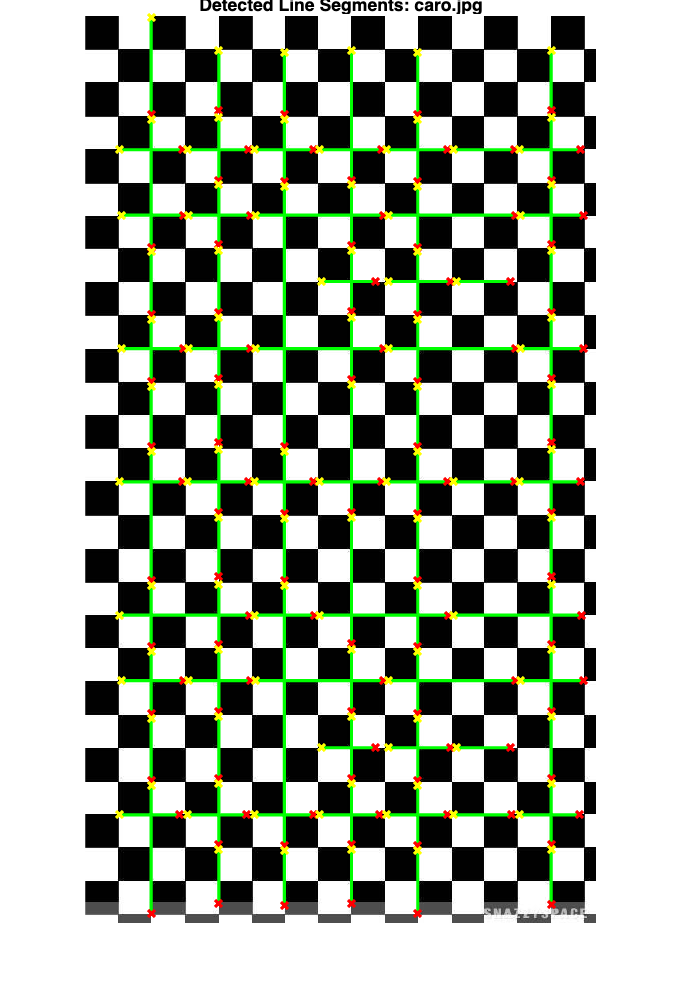

Image: caro.jpg -> Found 112 line segments.


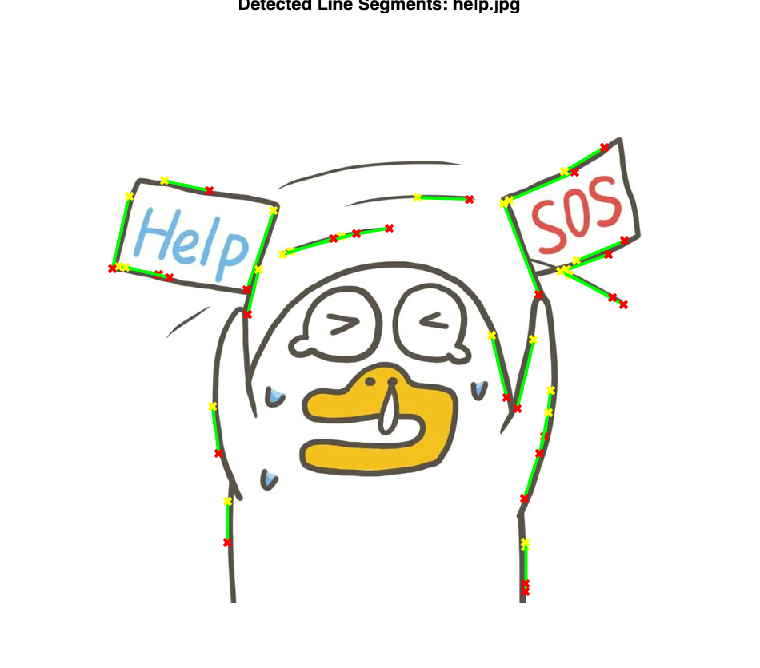

Image: help.jpg -> Found 26 line segments.


for i = 1:length(imageFiles)

    % Read an image
    I = imread(imageFiles{i});
    if isempty(I)
        error('Error reading the image.');
    end

    % Convert to grayscale if necessary
    if size(I, 3) == 3
        I_gray = rgb2gray(I);
    else
        I_gray = I;
    end

    % Detect edges using the Canny edge detector
    I_edge = edge(I_gray, 'canny');

    % Display the original and edge-detected images
    figure;
    subplot(1, 2, 1); imshow(I); title(['Source Image: ', imageFiles{i}], 'Interpreter','none');
    subplot(1, 2, 2); imshow(I_edge); title('Edges');
    
    % Next, compute the Hough transform and identify peaks (again, in the same way, like it was done):
    [H, theta, rho] = hough(I_edge);

    % Find peaks in the Hough transform accumulator
    % Note: you may have to change parameters for your images
    peaks = houghpeaks(H, 50, 'Threshold', 50);
    % Now, to implement the probabilistic variant, we will use the function lines = houghlines(I_edge, theta, rho, peaks, Name, Value). 
    % This is the same function that was used earlier, but now we have added name-value pair arguments to control various aspects of the line extraction.
    % Extract line segments with smaller FillGap and MinLength for shorter lines
    lines_p = houghlines(I_edge, theta, rho, peaks, 'FillGap', 5, 'MinLength', 50);

    % Here: 
    %       FillGap is a parameter that specifies the maximum distance (in pixels) between two line segments that can be combined into a single line.
    %           MinLength is the minimum len
    % Finally, plot the detected lines on the original image:

    figure;
    imshow(I); hold on;
    for k = 1:length(lines_p)
        xy = [lines_p(k).point1; lines_p(k).point2];
        plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'green');

        % Mark the start and end points
        plot(xy(1, 1), xy(1, 2), 'x', 'LineWidth', 2, 'Color', 'yellow');
        plot(xy(2, 1), xy(2, 2), 'x', 'LineWidth', 2, 'Color', 'red');
    end
    title(['Detected Line Segments: ', imageFiles{i}], 'Interpreter','none');
    hold off;

    % Print number of found line segments
    num_lines_p = length(lines_p);
    fprintf('Image: %s -> Found %d line segments.\n', imageFiles{i}, num_lines_p);

end

### **1.3 Classic Hough Transform for Lines (another approach)**

Let some image be given. Let select the contours using the Canny algorithm and apply the Hough transform using the `hough()` MATLAB function. 

# ***Self-work***

Take **three** arbitrary images and execute the classic Hough transform. Display the found lines and print their number. 

***Notes.**** You may have to change the Hough transform parameters to match your images.*

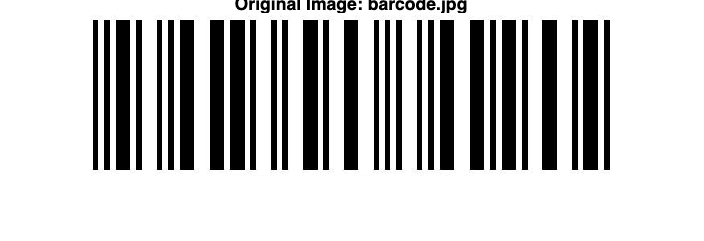

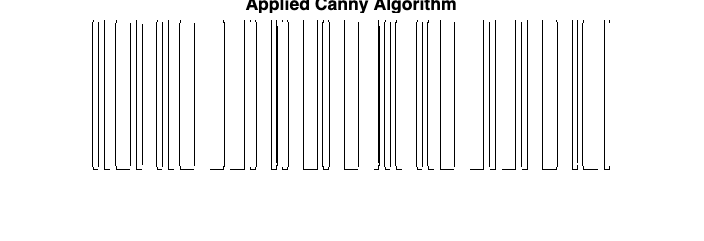

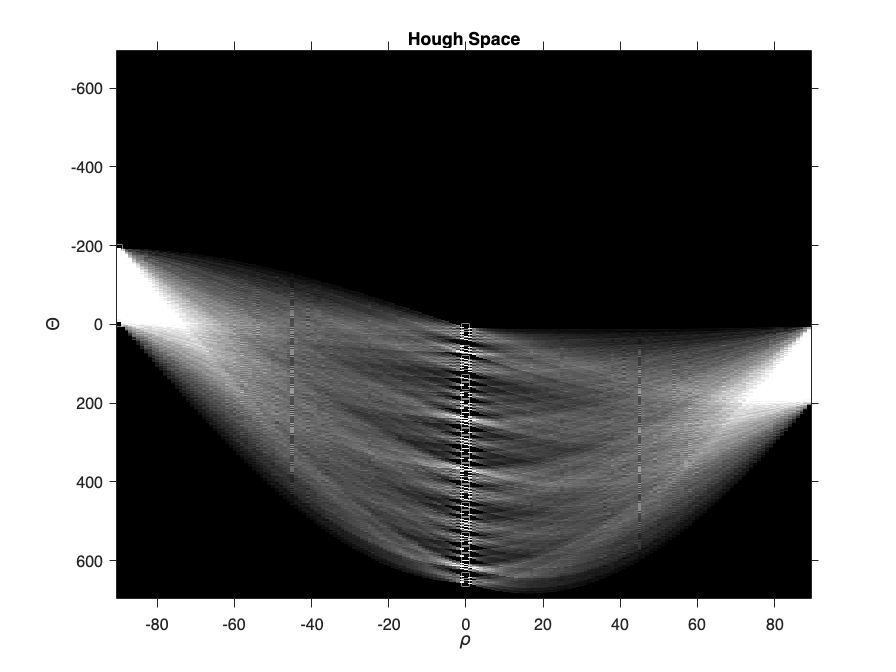

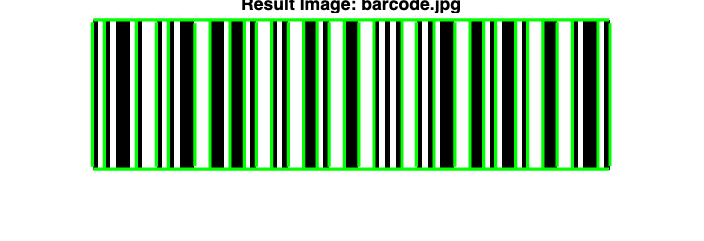

Image: barcode.jpg | Number of found lines: 34


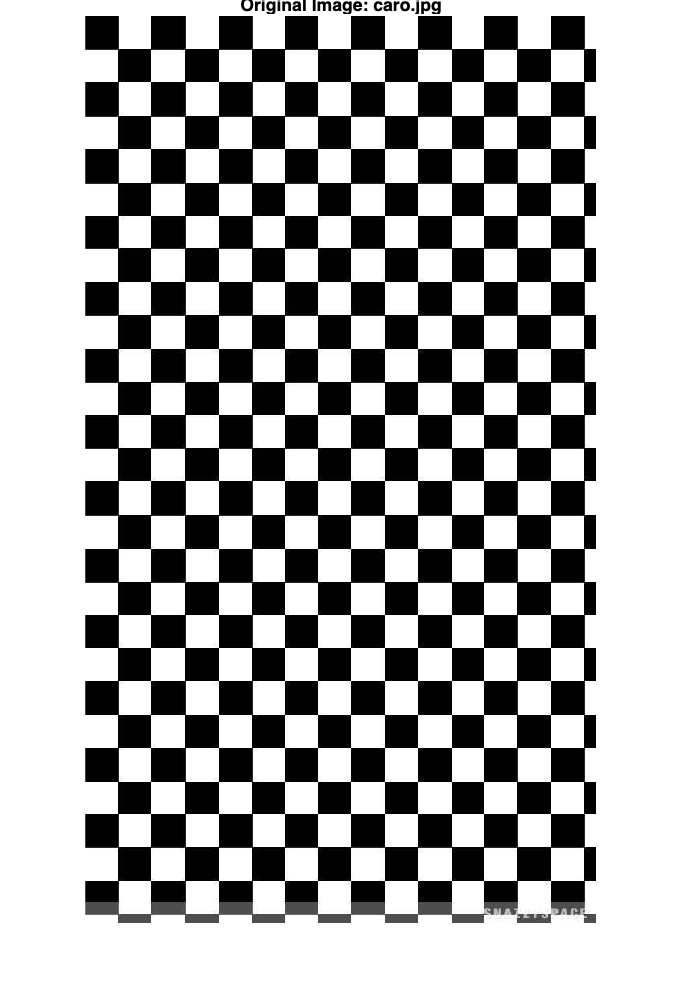

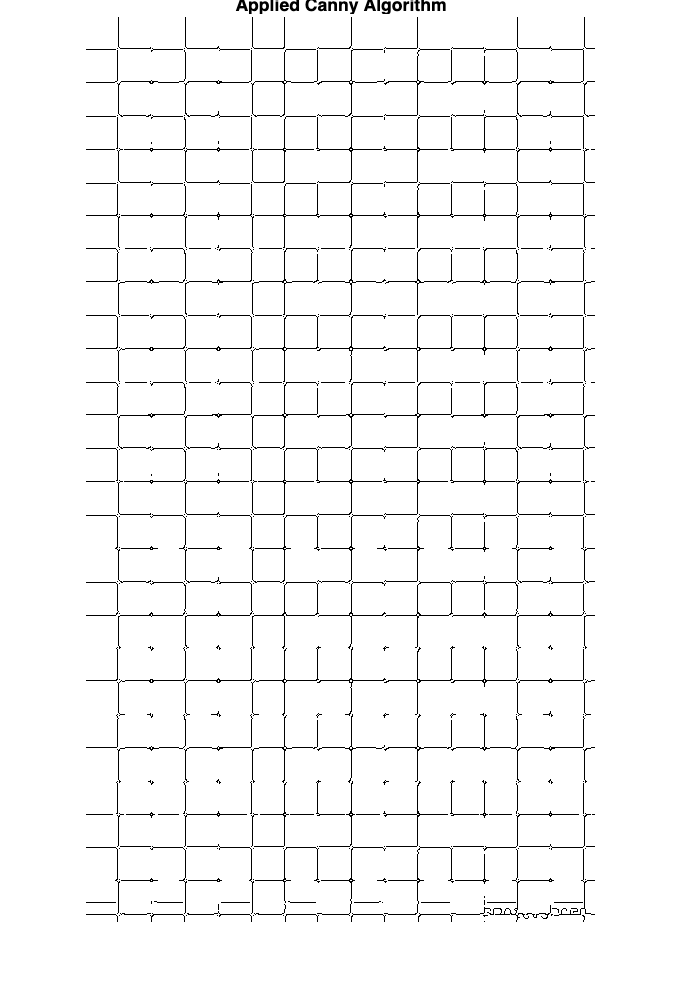

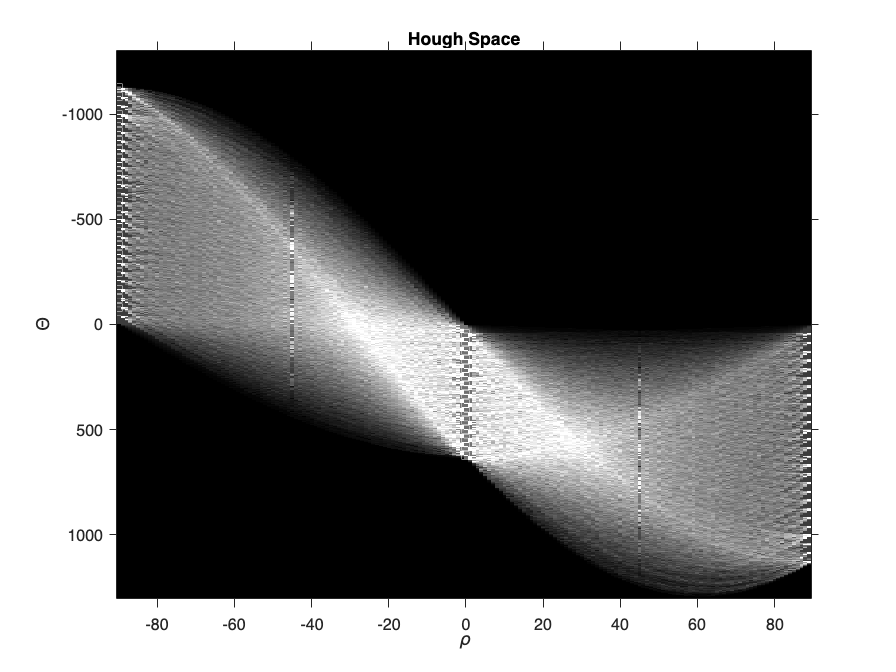

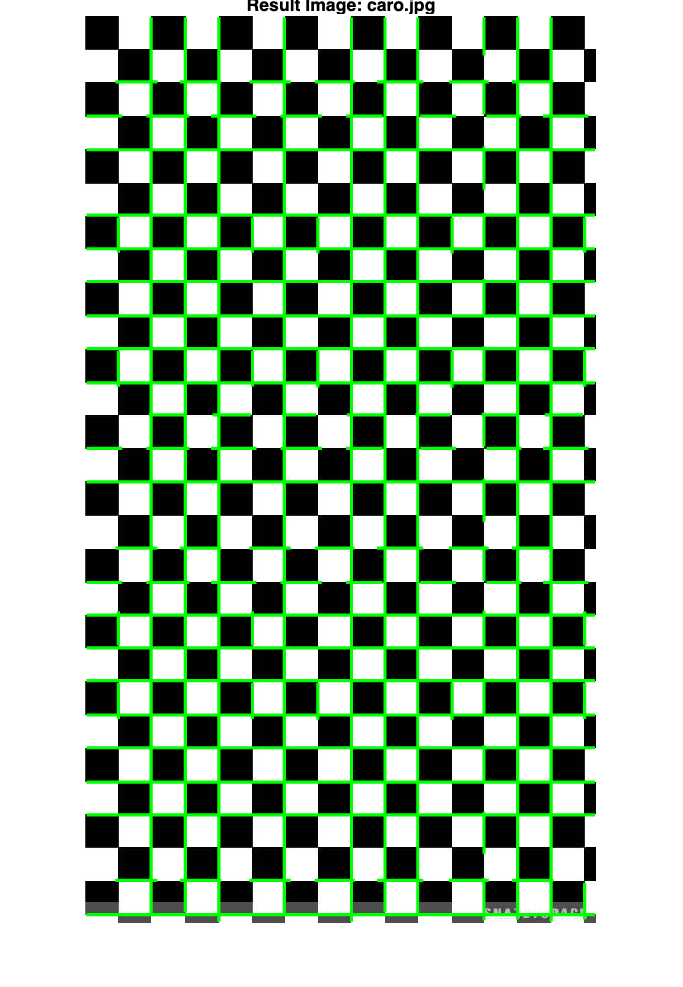

Image: caro.jpg | Number of found lines: 110


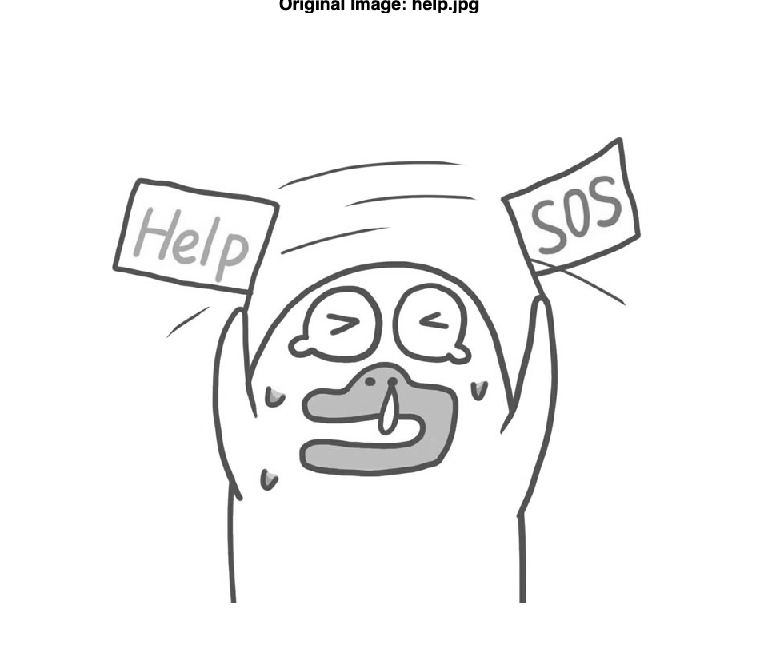

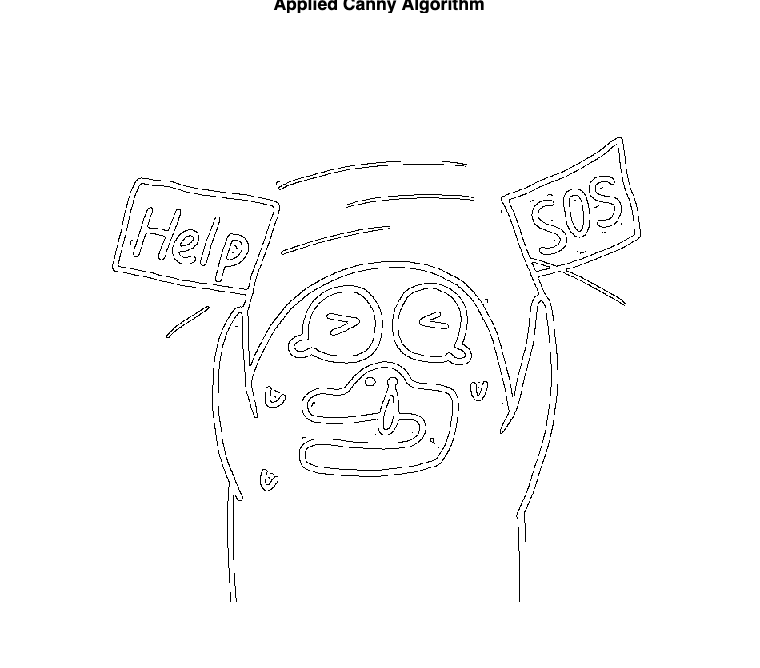

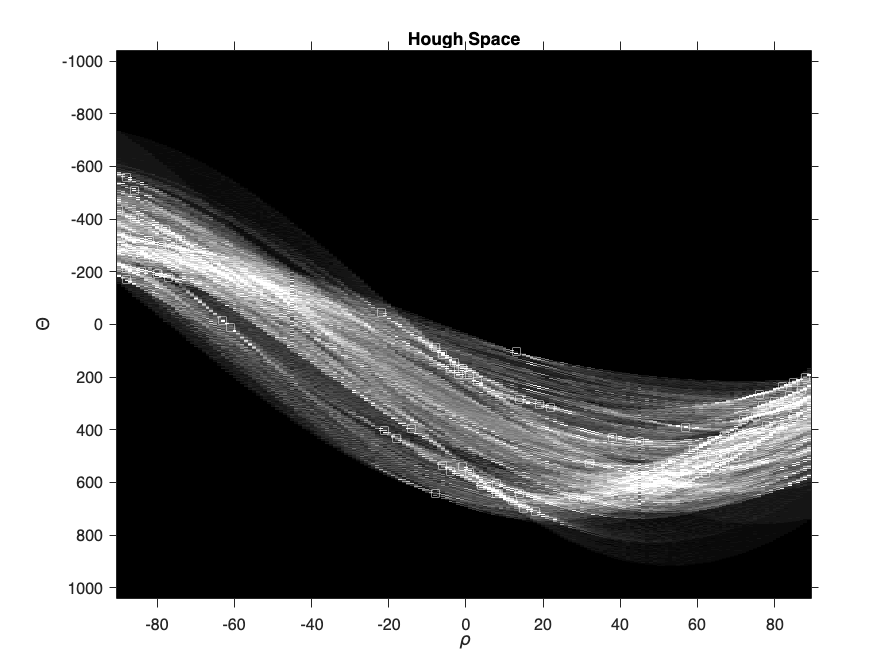

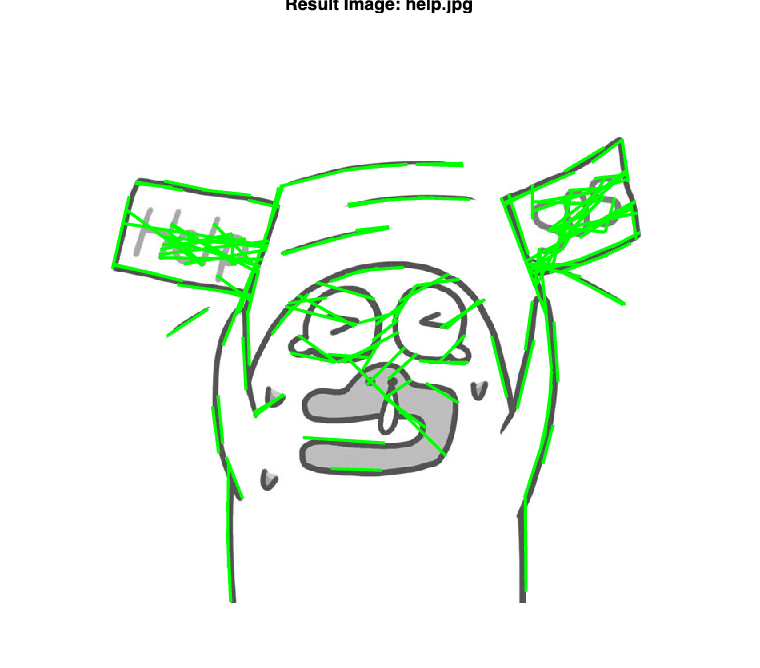

Image: help.jpg | Number of found lines: 141


% TODO Place your solution here
for i = 1:length(imageFiles)

    % Read image and convert to grayscale
    I0 = imread(imageFiles{i});
    if size(I0,3) == 3
        I = rgb2gray(I0);
    else
        I = I0;
    end

    figure;
    imshow(I);
    title('Original Image', 'Interpreter','none');

    % Canny edge detection
    Iedge = edge(I, 'Canny');

    figure;
    imshow(~Iedge);
    title('Applied Canny Algorithm');

    % Hough transform
    [H,Theta,rho] = hough(Iedge);

    % Show Hough space
    figure; imshow(imadjust(mat2gray(H)),[],'YData',rho,'XData',Theta,'InitialMagnification','fit');

    xlabel('\rho'), ylabel('\Theta')
    title('Hough Space');
    axis on, axis normal, hold on

    % Let’s calculate the peaks using the houghpeaks() function in the Hough space and plot them on the resulting image of the response functions:
    peaks = houghpeaks(H, 100, 'threshold', ceil(0.3 * max(H(:))));
    x = Theta(peaks(:,2));
    y = rho(peaks(:,1));
    plot(x, y, 's', 'color', 'white');
    
    % Based on the peaks, we determine the straight lines using the houghlines() MATLAB function and plot them on the original image:
    lines = houghlines(Iedge, Theta, rho, peaks);

    % Plot lines on the original image
    figure;
    imshow(I);
    title(['Result Image: ', imageFiles{i}], 'Interpreter','none');
    hold on
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    end
    hold off

    % Print number of found lines
    disp(['Image: ', imageFiles{i}, ' | Number of found lines: ', num2str(length(lines))]);

end

### **1.4 Probabilistic Hough Transform for Lines (another approach)**

Let's repeat again the same steps and calculate Probabilistic Hough Transform for Lines.

# ***Self-work***

Take **three** arbitrary images and execute **Probabilistic Hough Transform for Lines (another approach):**

- Display the Hough space, like it was done in **section 1.3.**

- Dispaly the found lines and print their number.

***Notes.**** You may have to change the Hough transform parameters to match your images.*

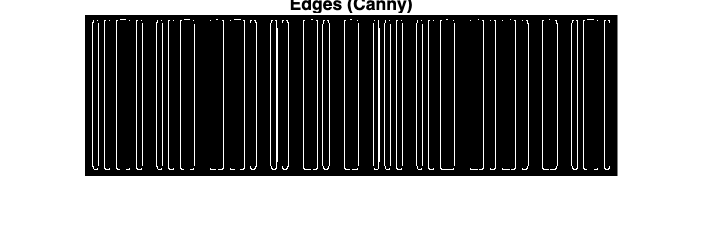

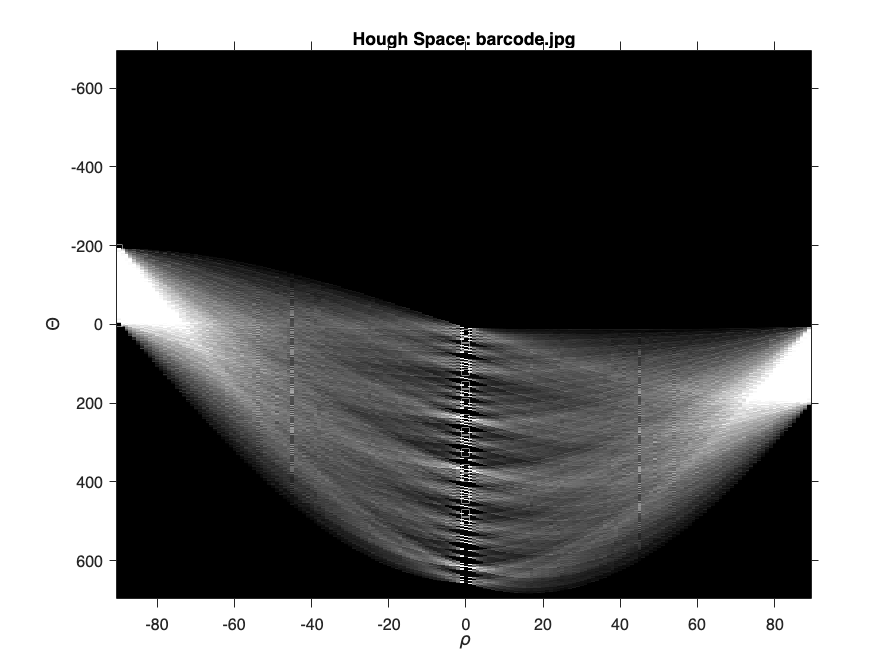

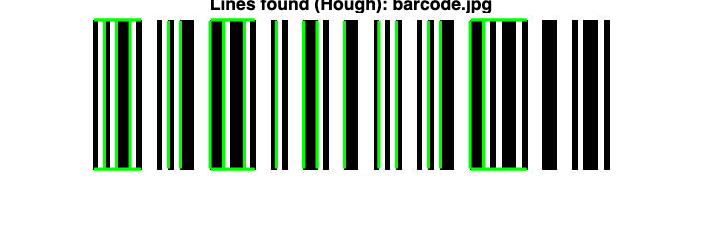

Image: barcode.jpg -> Lines found: 24


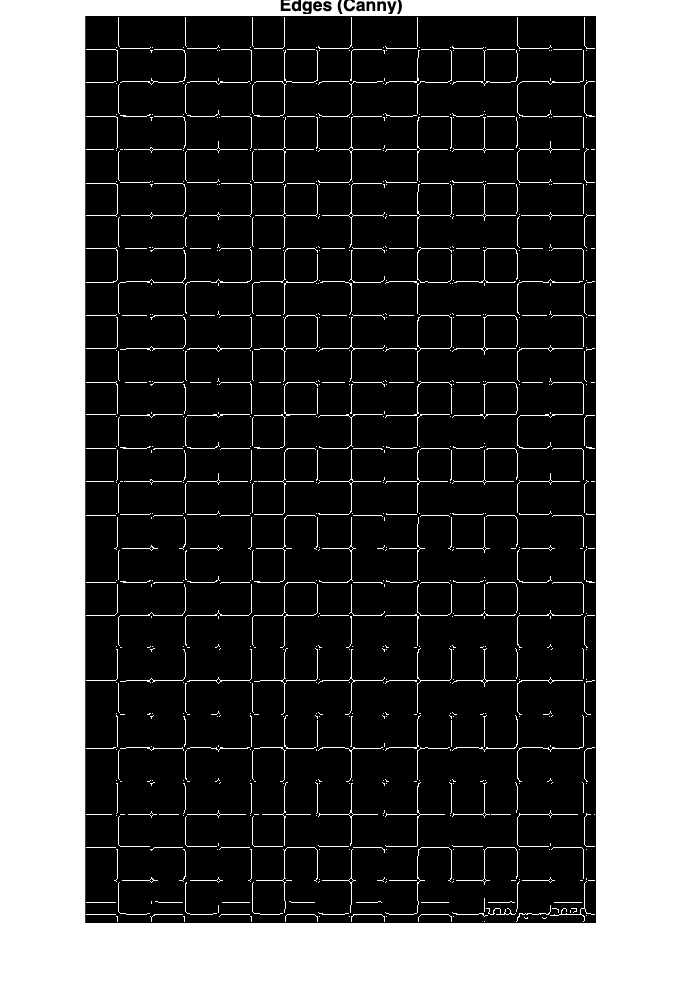

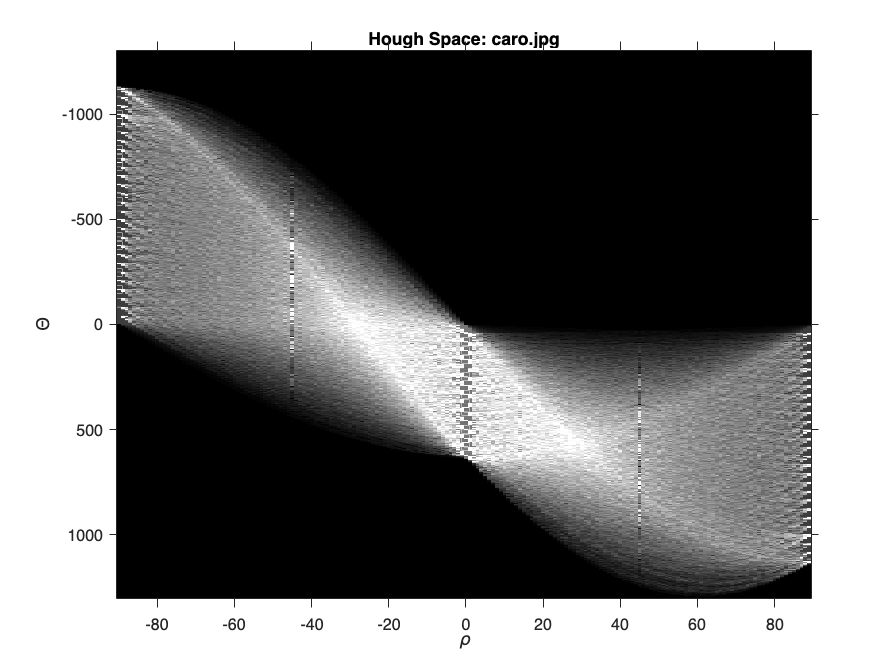

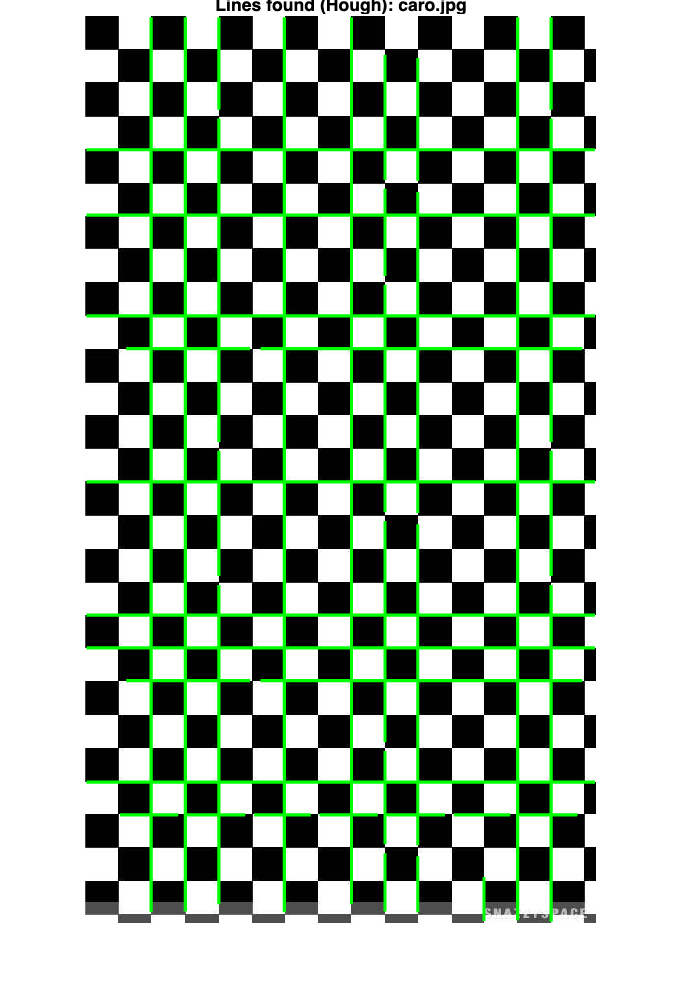

Image: caro.jpg -> Lines found: 42


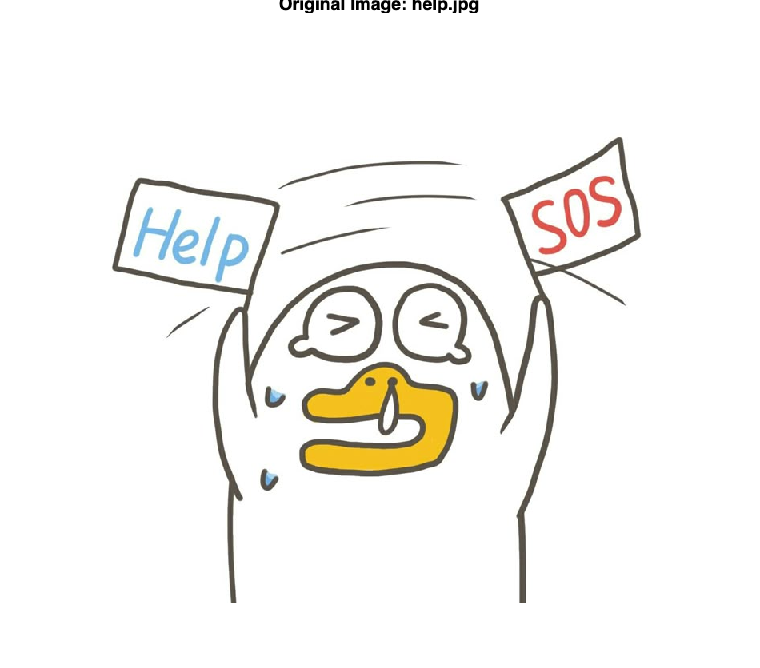

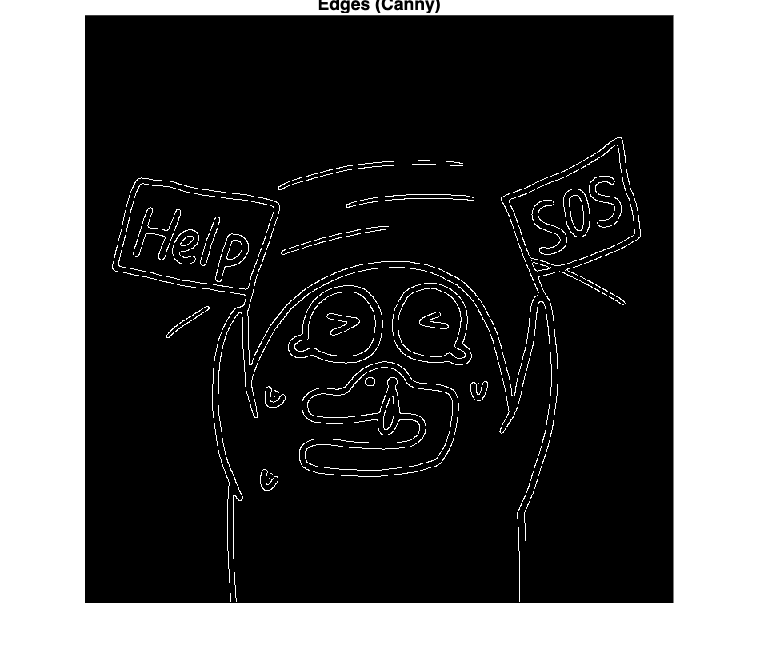

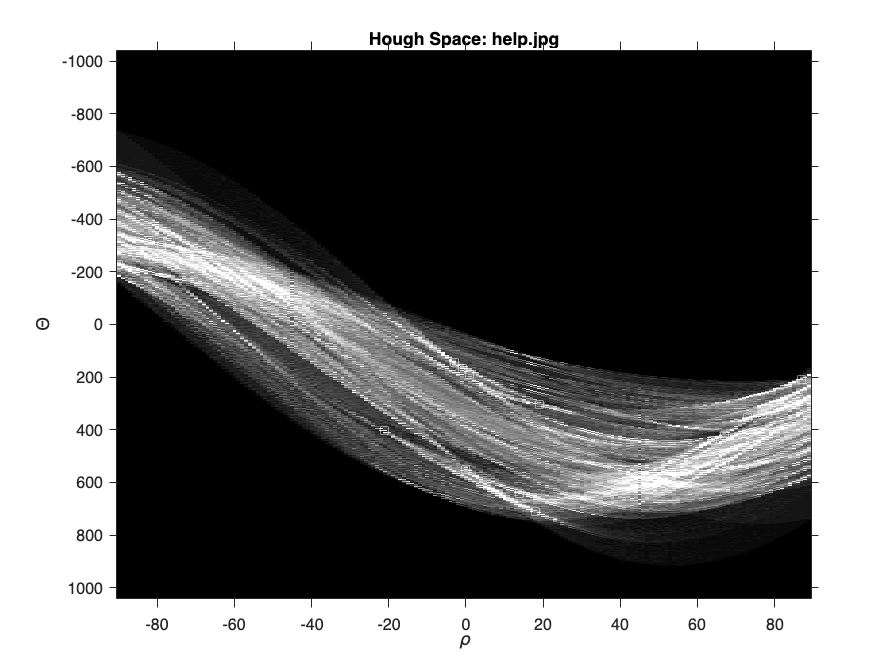

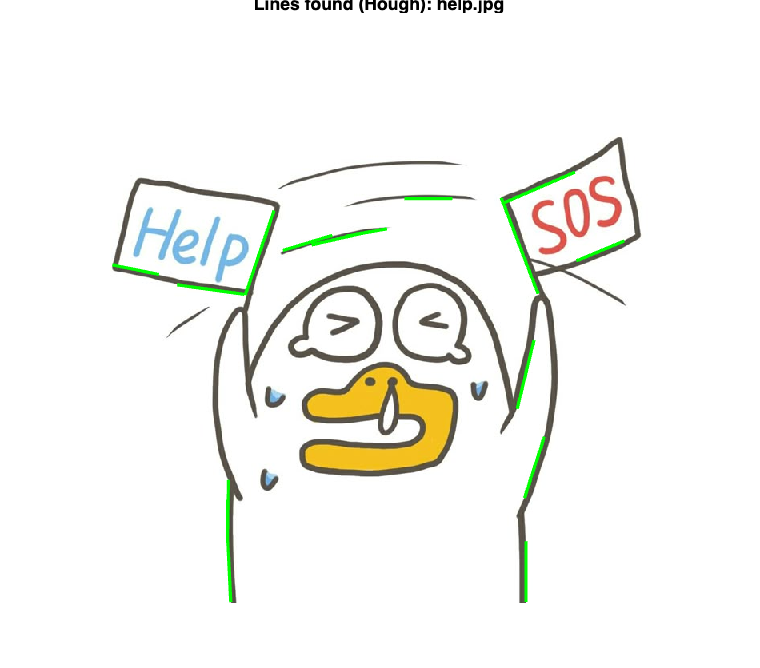

Image: help.jpg -> Lines found: 16


% TODO Place your solution here
for i = 1:length(imageFiles)

    % Read image and convert to grayscale if needed
    I = imread(imageFiles{i});
    if size(I,3) == 3
        I_gray = rgb2gray(I);
    else
        I_gray = I;
    end

    figure;
    imshow(I);
    title(['Original Image: ', imageFiles{i}], 'Interpreter','none');
    
    % Let's apply the Canny algorithm to the grayscale representation using edge() function and dispay it:
    BW = edge(I_gray, 'canny', [0.1 0.2], 2);

    figure;
    imshow(BW);
    title('Edges (Canny)');
    
    % Let’s calculate the peaks using the houghpeaks() function in the Hough space and plot them on the resulting image of the response functions:
    [H,theta,rho] = hough(BW);

    figure;
    imshow(imadjust(mat2gray(H)),[],'YData',rho,'XData',theta,'InitialMagnification','fit');
    xlabel('\rho'), ylabel('\Theta')
    title(['Hough Space: ', imageFiles{i}], 'Interpreter','none');
    axis on, axis normal, hold on

    % Peaks in Hough space + plot them
    P = houghpeaks(H, 20, 'threshold', ceil(0.5 * max(H(:))));
    x = theta(P(:,2));
    y = rho(P(:,1));
    plot(x, y, 's', 'color', 'white');

    lines = houghlines(BW, theta, rho, P, 'FillGap', 10, 'MinLength', 50);
    figure;
    imshow(I), hold on;
    title('Lines found (Hough): ', 'Interpreter','none');

    % Let's calculate and display statistical information:
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    end
    hold off;

    % Print number of found lines
    fprintf('Image: %s -> Lines found: %d\n', imageFiles{i}, length(lines));

end

## Task 2. Search for Circles

*Take three arbitrary images containing circles. Search for circles of a known radius range using the Hough transform. Plot the found circles on the original image and print the number of found circles.*

### 2.1 Hough Transform for Circles

In MATLAB, the Hough transform for circles can be implemented using the `imfindcircles()` function. This function detects circles in a grayscale or binary image using a circular Hough transform (CHT). The function returns the centers and radii of the detected circles.

Basic parameters of the `imfindcircles()` function:

- `ObjectPolarity` — `bright` (looking for light circles on a dark background) or `dark` (vice versa);

- `Method` — `PhaseCode` (fast) or `TwoStage` (accurate);

- `Sensitivity` — from 0 to 1 (the higher it is, the more false alarms);

- `EdgeThreshold` — threshold for borders (0-1, the higher, the stricter).

Firstly, let's preprocess the image to detect edges using the Canny edge detector:

# ***Self-work***

Take **three **arbitrary images and execute the Hough transform for circles. Display the found circles and print their number.

*Notes.* *You may have to change the *`imfindcircles()` *function parameters to match your images.*

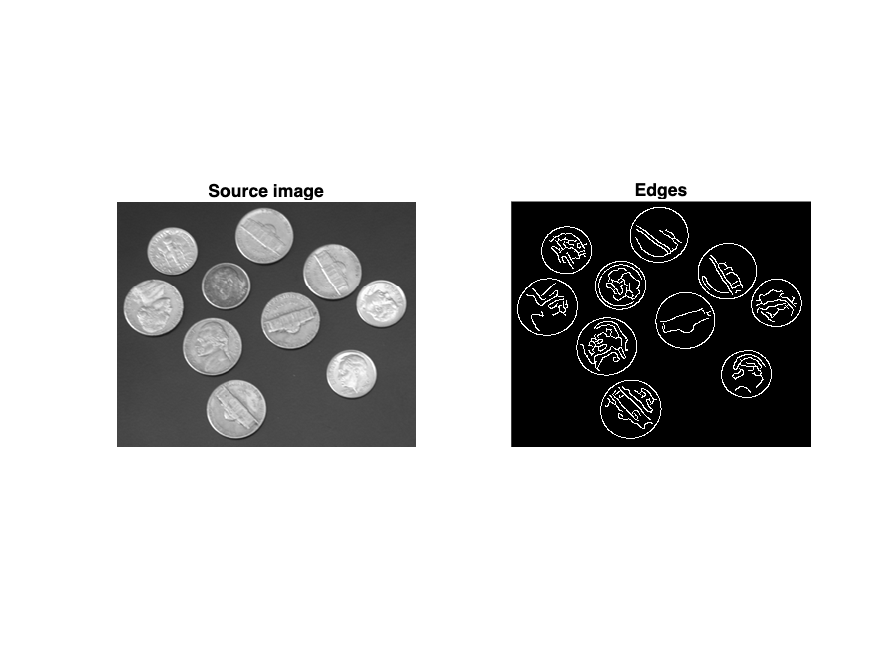

Image: coins.png -> Found 7 circles


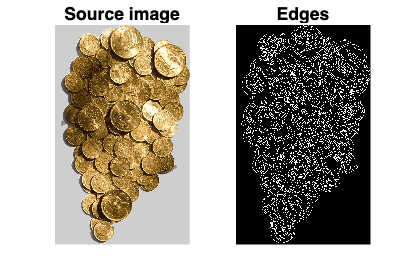

Image: coins2.jpg -> Found 28 circles


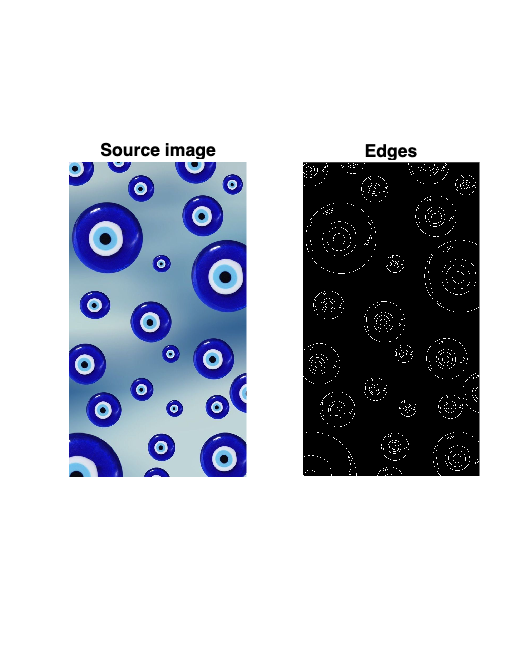

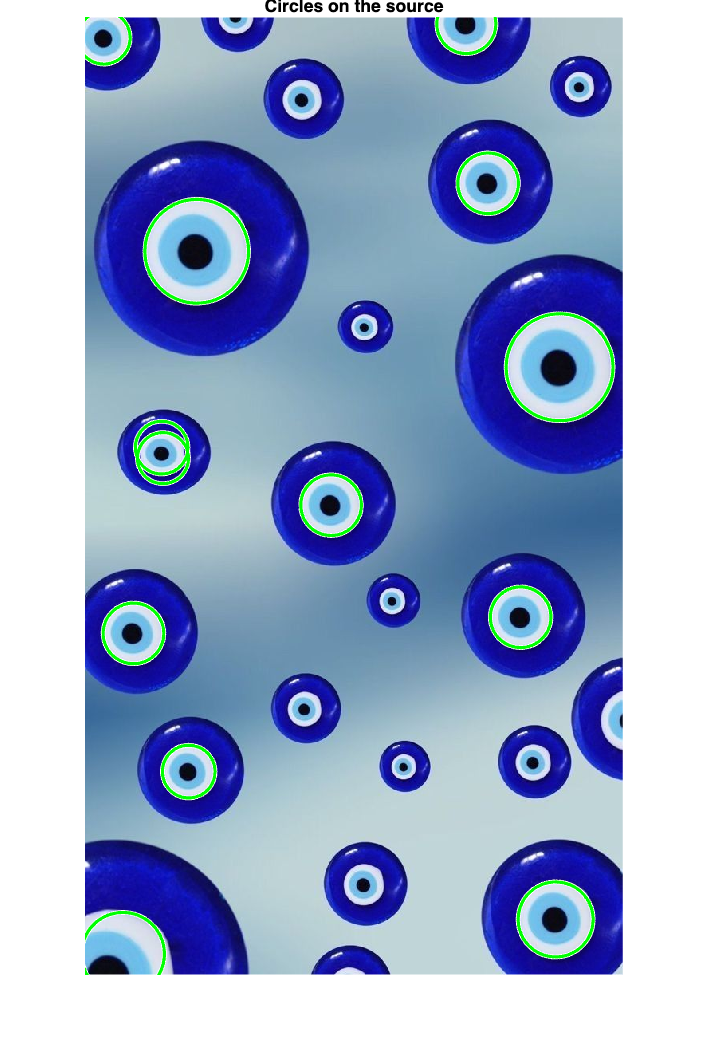

Image: eyes.jpg -> Found 13 circles


% TODO Place your solution here
clc; close all; clear;

imageFiles = {'coins.png', 'coins2.jpg', 'eyes.jpg'};

for i = 1:length(imageFiles)

    fn = imageFiles{i};
    I2 = imread(fn);
    if isempty(I2)
        error('Error reading file "%s"', fn);
    end
    if size(I2,3) == 3
        I2gray = rgb2gray(I2);
    else
        I2gray = I2;
    end
    % Pre-processing with Canny algorithm and display it
    I2edge = edge(I2gray, 'Canny', [0 50]/255);
    subplot(1,2,1); imshow(I2); title('Source image', 'Interpreter','none');
    subplot(1,2,2); imshow(I2edge); title('Edges');

    % Let's apply imfindcircles() function to detect all circles with radiuses in a range between 30 and 70 pixels:
    radiusRange = [30 70];

    [centers, radii, metric] = imfindcircles(I2gray, radiusRange, ...
        'ObjectPolarity', 'bright', ...
        'Method', 'TwoStage', ...
        'Sensitivity', 0.91, ...
        'EdgeThreshold', 0.05);
    

    % Let's display all found circles:
    if ~isempty(centers)

        figure('Name',['Circles: ', fn], 'NumberTitle','off');
        imshow(I2); hold on;
        viscircles(centers, radii, 'Color', 'green');
        title('Circles on the source', 'Interpreter','none');
        hold off;
        drawnow limitrate

        fprintf('Image: %s -> Found %d circles\n', fn, size(centers, 1));

    else
        fprintf('Image: %s -> No circles found\n', fn);
    end

end

# ***Self-work***

**Answer questions and conclude your work results.**

## **Questions **

Please answer the following questions:

 -  What is the main principle of the Hough transform?

** > **Основной принцип преобразования Хафа — «голосование» в пространстве параметров. Сначала на изображении выделяются точки границ (например, методом Canny). Далее каждая точка границы вносит вклад в аккумулятор (Hough space) для наборов параметров возможных примитивов. Пики в аккумуляторе соответствуют параметрам объектов, которые поддерживаются большим числом граничных точек. В работе это реализовано через hough() → houghpeaks() → houghlines().

 - May the Hough transform be used to find arbitrary contours that cannot be described analytically?

** > **В рамках данной лабораторной работы преобразование Хафа используется для поиска геометрических примитивов, которые имеют параметрическое описание: прямых (параметры \rho,\theta) и окружностей (центр и радиус, задаваемый диапазоном). Поэтому для произвольных контуров, которые нельзя описать через такие параметры и которые не сводятся к набору линий/дуг окружностей, классический подход, применённый в работе, не предназначен напрямую. На практике его применяют именно тогда, когда контур можно представить как набор параметризуемых примитивов.

 - What are the *recurrent* and *generalized* Hough transforms?

** >** Обобщённое преобразование Хафа — это расширение идеи «голосования в пространстве параметров» на более широкий класс задач, когда нужно искать не только прямые и окружности, а более сложные объекты, требующие другой (более общей) постановки и большего числа параметров.Рекуррентное (итеративное) преобразование Хафа — вариант, в котором поиск выполняется поэтапно: параметры и/или область поиска уточняются итерациями, что позволяет сделать вычисления более устойчивыми и эффективными при усложнении задачи и увеличении пространства параметров.

 -  What are the ways of parametrization in the Hough transform?

** > **Параметризация — это выбор набора параметров, описывающих искомый примитив в Hough space. Типичные примеры:

**1) Прямая:**

        • y = kx + b (неудобно для вертикальных прямых);• наиболее распространённая форма (нормальная): 


$$x\cos{\Theta}+y\sin{\Theta}=\rho,$$


        where $\rho$ — radius vector drawn from the origin to the line; $\Theta$ — inclination angle of the radius vector

**2) Окружность:**

 
$$(x-x_0)^2+(y-y_0)^2=R^2$$


параметры: центр $(x_0, y_0)$ и радиус r (часто радиус ищут в известном диапазоне, как в imfindcircles).

**3) Более сложные фигуры (например, эллипс):** центр, полуоси, угол поворота и т.д. — то есть пространство параметров становится многомерным, поэтому часто используют вероятностные/итеративные варианты для ускорения.

## **Conclusion**

What have you learned with this task? Don't forget to conclude it.

 > В ходе выполнения данной работы мы изучили преобразование Хафа как метод обнаружения геометрических примитивов на изображении, основанный на «голосовании» в пространстве параметров и поиске пиков в аккумуляторе. Мы убедились, что этап предварительной обработки (прежде всего выделение границ алгоритмом Canny) существенно влияет на итоговый результат, поскольку именно по точкам границ формируется аккумулятор. На практике мы реализовали классическое преобразование Хафа для прямых с использованием функций hough, houghpeaks и houghlines, визуализировали найденные линии и получилли количественные характеристики (число линий, минимальная и максимальная длина). Также я рассмотрли вероятностный вариант извлечения линий с параметрами FillGap и MinLength, что позволило лучше контролировать разрывы и отфильтровывать короткие шумовые отрезки. Кроме того, мы применили круговое преобразование Хафа с помощью imfindcircles для поиска окружностей в заданном диапазоне радиусов и оценили результат по количеству найденных окружностей и их визуализации. В целом, мы сделали вывод, что преобразование Хафа эффективно для поиска прямых и окружностей, но требует корректного подбора параметров (порогов, числа пиков, диапазона радиусов) и аккуратной предобработки изображения для получения устойчивых и точных результатов.